%1.1 
clear
load("Ad.mat")
load("Ad2.mat")
load("chips20.mat")
load("illum.mat")
load("M_XYZ2RGB.mat")

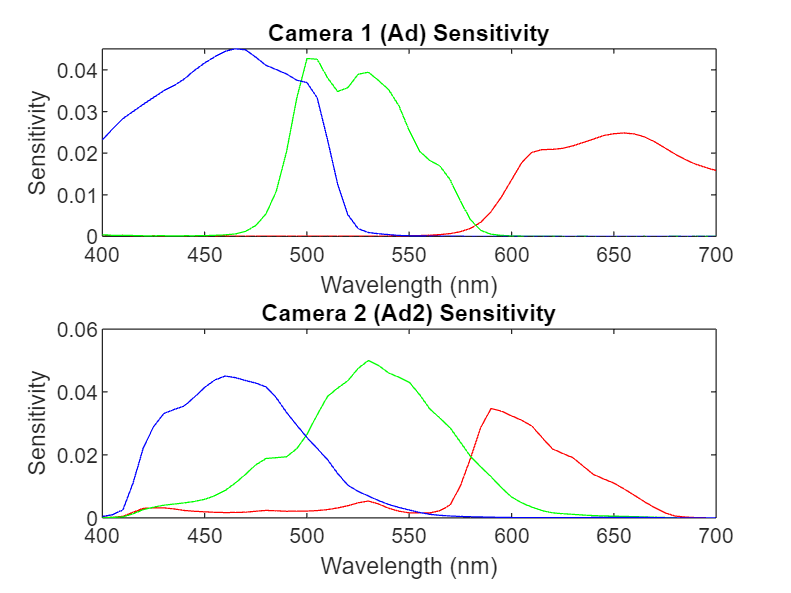


%load("Optimize_poly.m")
%load("Polynomial_regression.m")
%load("showRGB.m")
%load("xyz.mat")
%load("xyz2lab.m")

lambda = 400:5:700;
figure;
subplot(2,1,1);
plot(lambda, Ad(:,1), 'r', lambda, Ad(:,2), 'g', lambda, Ad(:,3), 'b');
title('Camera 1 (Ad) Sensitivity');
xlabel('Wavelength (nm)'); ylabel('Sensitivity');

subplot(2,1,2);
plot(lambda, Ad2(:,1), 'r', lambda, Ad2(:,2), 'g', lambda, Ad2(:,3), 'b');
title('Camera 2 (Ad2) Sensitivity');
xlabel('Wavelength (nm)'); ylabel('Sensitivity');

1.1 No, looking at the graph they are responding differently for each colour. There will be a big difference close to 400nm since Camera 2 bearly has any sensitivity.

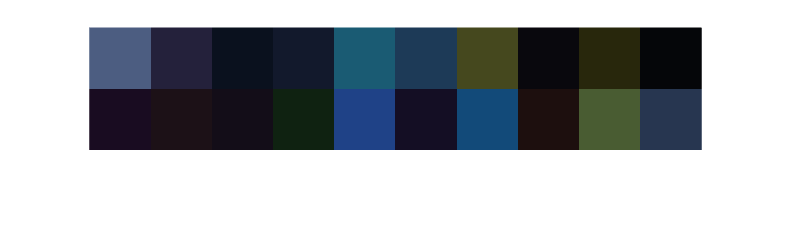

%1.2
clf
d = Ad'*(chips20.*CIED65)';

RGB_raw_D65_Ad = d;
showRGB2(RGB_raw_D65_Ad')

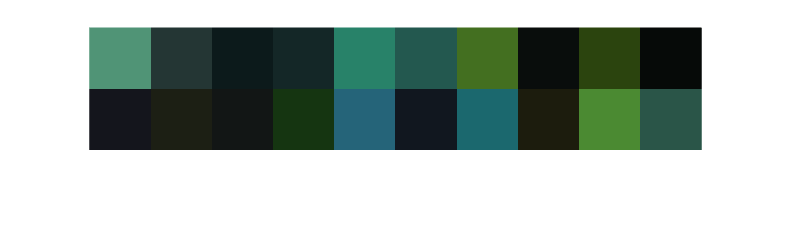

clf
d = Ad2'*(chips20.*CIED65)';

RGB_raw_D65_Ad2 = d;
showRGB(RGB_raw_D65_Ad2');

1.2 Different sensitivity, Camera 1 does is more blue and Camera 2 is more green. 

%2.1 
e = ones(1,61);
normFacAd = Ad' * e'

normFacAd =     0.4635
    0.5646
    0.8585


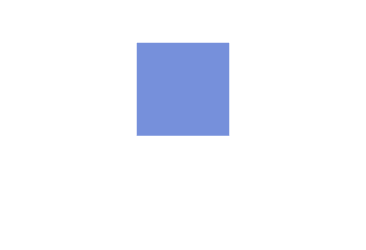

showRGB(normFacAd')

normFacAd2 = Ad2' * e'

normFacAd2 =     0.4726
    0.8747
    0.7420


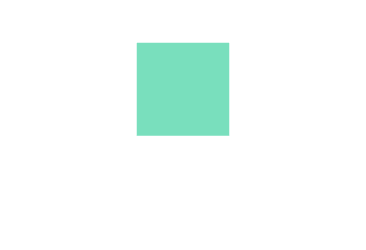

showRGB(normFacAd2')

 2.1 It reflects the characteristics of the Camera by having high blue values for Camera 1. Same goes for Camera 2 but with green.

%2.2
RGB_cal_D65_Ad = RGB_raw_D65_Ad./normFacAd

RGB_cal_D65_Ad =     0.6428    0.3014    0.0880    0.1533    0.2163    0.2452    0.5819    0.0744    0.3368    0.0433    0.2098    0.2395    0.1591    0.1259    0.2644    0.1698    0.1510    0.2483    0.6172    0.3261
    0.6472    0.2262    0.1154    0.1730    0.6334    0.4057    0.5001    0.0563    0.2740    0.0438    0.0828    0.1189    0.0915    0.2350    0.4598    0.0950    0.5112    0.1067    0.6405    0.3776
    0.5890    0.2695    0.1377    0.1998    0.5237    0.3977    0.1373    0.0614    0.0560    0.0429    0.1502    0.1032    0.1085    0.0764    0.6166    0.1643    0.5507    0.0653    0.2300    0.3650


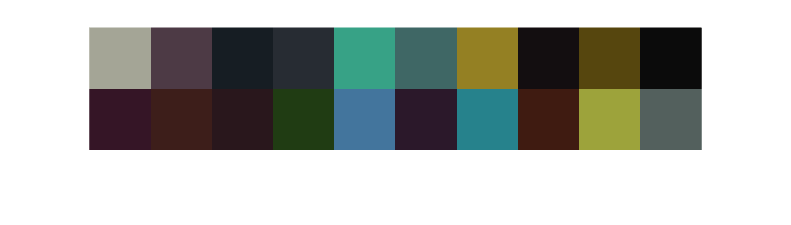

showRGB(RGB_cal_D65_Ad')

RGB_cal_D65_Ad2 = RGB_raw_D65_Ad2./normFacAd2

RGB_cal_D65_Ad2 =     0.6613    0.2990    0.0978    0.1657    0.3294    0.2923    0.5542    0.0749    0.3573    0.0456    0.1628    0.2290    0.1489    0.1704    0.3085    0.1451    0.2281    0.2303    0.6211    0.3525
    0.6617    0.2436    0.1154    0.1762    0.5830    0.3935    0.4961    0.0598    0.3067    0.0449    0.0932    0.1395    0.1001    0.2398    0.4476    0.1036    0.4646    0.1277    0.6194    0.3814
    0.6211    0.2761    0.1417    0.2058    0.5538    0.4166    0.1677    0.0634    0.0756    0.0446    0.1497    0.1077    0.1111    0.0922    0.6380    0.1648    0.5790    0.0710    0.2666    0.3812


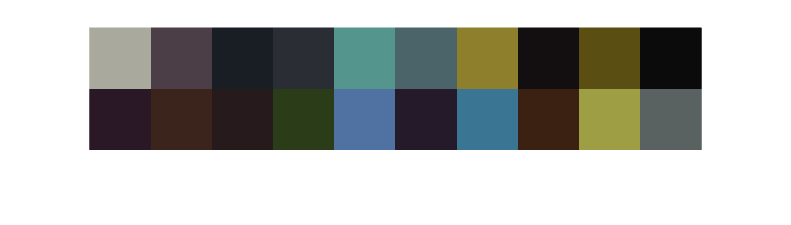

showRGB(RGB_cal_D65_Ad2')

2.2 They are very similar now but not exactly the same colours. There is a slight differance when looking at the exact RGB values which could be because of non-linear scaling. 

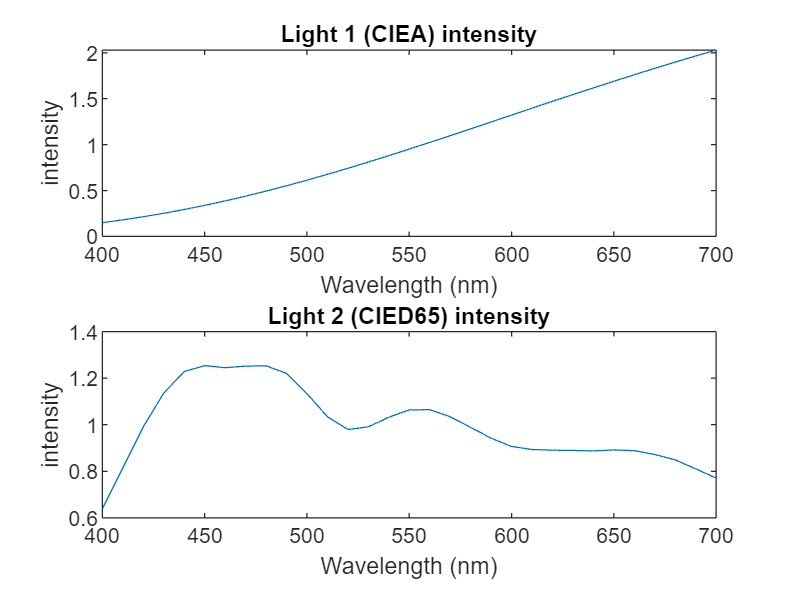

%2.3

figure;
subplot(2,1,1);
plot(lambda, CIEA);
title('Light 1 (CIEA) intensity');
xlabel('Wavelength (nm)'); ylabel('intensity');

subplot(2,1,2);
plot(lambda, CIED65);
title('Light 2 (CIED65) intensity');
xlabel('Wavelength (nm)'); ylabel('intensity');

2.3 They emit a diffrent amount of each colour in the spectrum. D65 daylight has a higher intensity on lower wave lengths ~450, while tungsten filament light emits more of the higher wave lengths.

%2.4 



clf
d = Ad'*(chips20.*CIEA)';

RGB_raw_A_Ad = d;
RGB_cal_A_Ad = RGB_raw_A_Ad./normFacAd

RGB_cal_A_Ad =     1.2120    0.5681    0.1653    0.2878    0.3971    0.4593    1.1028    0.1398    0.6312    0.0814    0.4031    0.4516    0.3003    0.2317    0.4979    0.3243    0.2803    0.4694    1.1652    0.6120
    0.4910    0.1688    0.0841    0.1274    0.4629    0.2984    0.4012    0.0421    0.2365    0.0330    0.0590    0.0946    0.0684    0.1949    0.3252    0.0676    0.3584    0.0876    0.5025    0.2838
    0.2105    0.0928    0.0479    0.0695    0.1988    0.1438    0.0649    0.0214    0.0229    0.0152    0.0488    0.0364    0.0373    0.0297    0.2140    0.0539    0.2042    0.0241    0.1034    0.1294


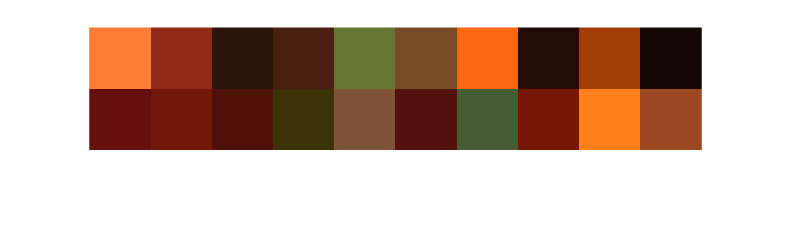

showRGB2(RGB_cal_A_Ad')

2.4 The image becomes more light because illuminant A has higher intensity for red light (higher wave lengths). 

%2.5
A_R = ones(1,61);

AdALightFac = Ad'*(A_R.*CIEA)';
RGB_cal_A_Ad = RGB_raw_A_Ad./AdALightFac

RGB_cal_A_Ad =     0.7340    0.3441    0.1001    0.1743    0.2405    0.2782    0.6679    0.0847    0.3823    0.0493    0.2441    0.2735    0.1819    0.1403    0.3016    0.1964    0.1697    0.2843    0.7057    0.3706
    0.6283    0.2161    0.1077    0.1630    0.5924    0.3819    0.5134    0.0539    0.3027    0.0422    0.0755    0.1210    0.0875    0.2494    0.4162    0.0864    0.4586    0.1121    0.6430    0.3632
    0.5257    0.2318    0.1195    0.1737    0.4966    0.3590    0.1620    0.0535    0.0571    0.0380    0.1218    0.0909    0.0931    0.0741    0.5346    0.1347    0.5100    0.0602    0.2583    0.3231


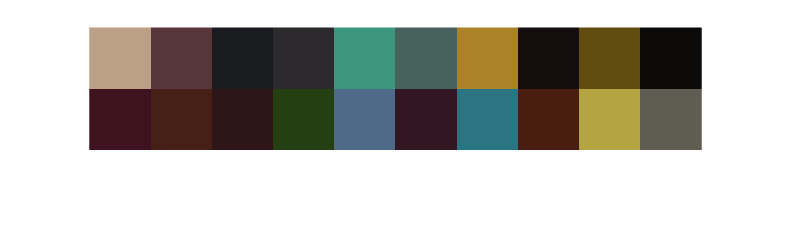

showRGB(RGB_cal_A_Ad');


AdD65LightFac = Ad'*(A_R.*CIED65)';
RGB_cal_D65_Ad = RGB_raw_D65_Ad./AdD65LightFac

RGB_cal_D65_Ad =     0.7323    0.3434    0.1003    0.1747    0.2465    0.2794    0.6630    0.0848    0.3837    0.0493    0.2390    0.2729    0.1812    0.1435    0.3013    0.1935    0.1720    0.2829    0.7032    0.3716
    0.6115    0.2137    0.1090    0.1635    0.5984    0.3833    0.4725    0.0532    0.2589    0.0414    0.0782    0.1124    0.0865    0.2221    0.4345    0.0898    0.4831    0.1008    0.6051    0.3568
    0.5183    0.2372    0.1212    0.1758    0.4608    0.3499    0.1208    0.0540    0.0493    0.0377    0.1322    0.0908    0.0955    0.0672    0.5425    0.1446    0.4846    0.0575    0.2024    0.3212


showRGB(RGB_cal_A_Ad');

2.5 Comparing the rgb values we can now see how close the values are. Whitepoint normalisation works well. :))

%3.1
load("xyz.mat")
XYZ_D65_ref = xyz'*(chips20.*CIED65)';

Y = 100;
XYZNormFac = Y / (xyz(:,2)'*CIED65')

XYZNormFac = 4.6460


XYZ_D65_ref = (XYZ_D65_ref.*XYZNormFac)'

XYZ_D65_ref =    66.5076   67.2653   61.0087
   29.1415   25.9561   28.3929
   10.3354   10.4588   14.4753
   17.0944   16.8158   20.9340
   37.2524   49.3000   50.2915
   31.4696   35.3276   40.5003
   51.8681   57.1830   10.0020
    7.1516    6.4429    6.4265
   35.7168   38.2742    5.4609
    4.5704    4.5382    4.4085



showRGB(XYZ_D65_ref')

%3.2 

XYZ_cal_D65_Ad = (inv(M_XYZ2RGB) * RGB_cal_D65_Ad)';

[Mean, Max] = calcDeltaE(XYZ_D65_ref, XYZ_cal_D65_Ad)

Mean = 10.7389

Max = 29.5862

The mean is quite large

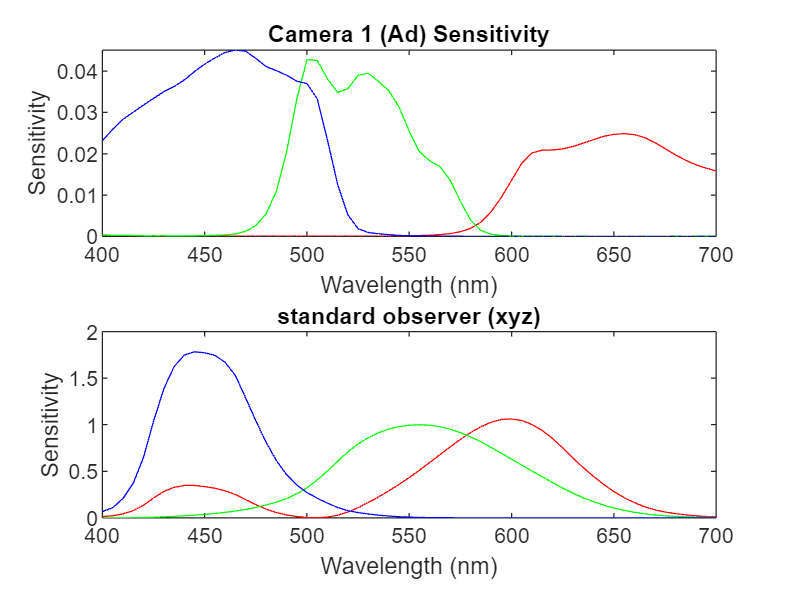

%3.3
lambda = 400:5:700;
figure;
subplot(2,1,1);
plot(lambda, Ad(:,1), 'r', lambda, Ad(:,2), 'g', lambda, Ad(:,3), 'b');
title('Camera 1 (Ad) Sensitivity');
xlabel('Wavelength (nm)'); ylabel('Sensitivity');

subplot(2,1,2);
plot(lambda, xyz(:,1), 'r', lambda, xyz(:,2), 'g', lambda, xyz(:,3), 'b');
title('standard observer (xyz)');
xlabel('Wavelength (nm)'); ylabel('Sensitivity');

3.3 The standard observer reacts way way more to the colour spectrum. The standard observer is also has smoother curves. It also has red at wave length 450nm. 

%3.4 

RGB_cal_D65_Ad 

RGB_cal_D65_Ad =     0.7323    0.3434    0.1003    0.1747    0.2465    0.2794    0.6630    0.0848    0.3837    0.0493    0.2390    0.2729    0.1812    0.1435    0.3013    0.1935    0.1720    0.2829    0.7032    0.3716
    0.6115    0.2137    0.1090    0.1635    0.5984    0.3833    0.4725    0.0532    0.2589    0.0414    0.0782    0.1124    0.0865    0.2221    0.4345    0.0898    0.4831    0.1008    0.6051    0.3568
    0.5183    0.2372    0.1212    0.1758    0.4608    0.3499    0.1208    0.0540    0.0493    0.0377    0.1322    0.0908    0.0955    0.0672    0.5425    0.1446    0.4846    0.0575    0.2024    0.3212


C = XYZ_D65_ref;
D = RGB_cal_D65_Ad';

A = pinv(D)*C

A =    57.8087   35.4363    4.3470
   32.8479   80.8301  -17.5626
    5.8561  -17.6682  131.0000



est_XYZ_val = D*A;

[Mean, Max] = calcDeltaE(C,est_XYZ_val)

Mean = 2.1977

Max = 5.8376

3.4 linear regression is a great way of finding the optimal matrix A, Pinverse is cool, the mean and max are much better now.

%3.5
A_poly = Optimize_poly(D',C');

est_XYZ_poly = Polynomial_regression(D',A_poly)';
[Mean, Max] = calcDeltaE(C,est_XYZ_poly)

Mean = 1.0238

Max = 3.1053

3.5 This gives a better result than previous methods. Using polynomial regression gives the best result since the colour spectrum is best described by polynomials. 